# **Piezoelectric material properties from datasheet to one in COMSOL Multiphysics**

**2023-01-17**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

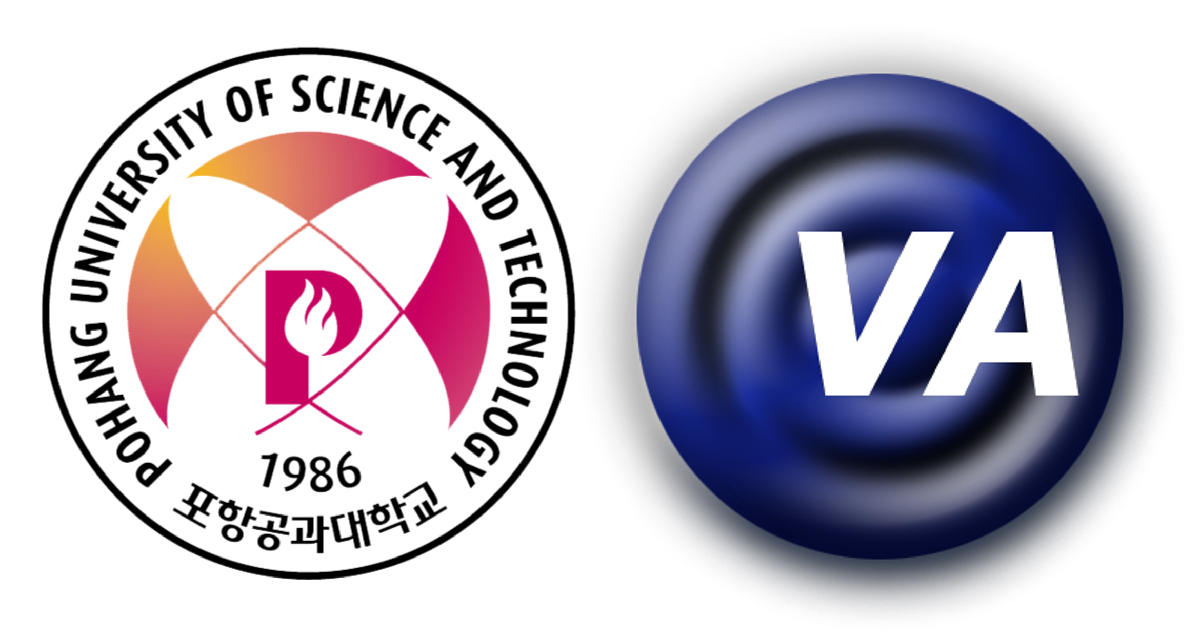

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

## References

[https://www.comsol.com/blogs/piezoelectric-materials-understanding-standards/](https://www.comsol.com/blogs/piezoelectric-materials-understanding-standards/)

[https://doc.comsol.com/5.5/doc/com.comsol.help.sme/sme_ug_theory.06.23.html#3440115](https://doc.comsol.com/5.5/doc/com.comsol.help.sme/sme_ug_theory.06.23.html#3440115)

[https://support.onscale.com/hc/en-us/articles/360002073378-Calculating-Piezoelectric-Material-Properties-from-Material-Datasheet](https://support.onscale.com/hc/en-us/articles/360002073378-Calculating-Piezoelectric-Material-Properties-from-Material-Datasheet)

[https://www.efunda.com/formulae/solid_mechanics/mat_mechanics/hooke_orthotropic.cfm](https://www.efunda.com/formulae/solid_mechanics/mat_mechanics/hooke_orthotropic.cfm)

[https://www.efunda.com/formulae/solid_mechanics/mat_mechanics/strain.cfm#engstrain](https://www.efunda.com/formulae/solid_mechanics/mat_mechanics/strain.cfm#engstrain)

## from Datasheet

cE = Inf(6);
dET = zeros(3,6);
% Fuji ceramics, C-21
cE(1,1) = 8.3e10;
% cE(1,1) = 6.4e10;
cE(3,3) = 6.4e10;
cE(5,5) = 2.3e10;
% cE(5,5) = 6.4e10;
nu      = 0.29;
% nu      = 0;
% dET(3,1)= -131e-12;
dET(3,3)= 288e-12;
% dET(1,5)= 634e-12;

% % Fuji ceramics, C-6
% cE(1,1) = 6.2e10;
% cE(3,3) = 4.9e10;
% cE(5,5) = 1.9e10;
% nu      = 0.32;
% dET(3,1)= -210e-12;
% dET(3,3)= 472e-12;
% dET(1,5)= 758e-12;


## Strain-charge form

### **Compliance matrix, **$s_{\mathrm{E}}$

cE(2,2) = cE(1,1);
cE(4,4) = cE(5,5);
cE(6,6) = cE(1,1)/(2*(1+nu));

sE_T = cE.^(-1);
sE_T(2,3) = -nu*sE_T(3,3);
sE_T(1,3) = sE_T(2,3);
sE_T(1,2) = -nu*sE_T(2,2);

sE = sE_T + triu(sE_T,1)'

sE = 1.0e-10 *

    0.1205   -0.0349   -0.0453         0         0         0
   -0.0349    0.1205   -0.0453         0         0         0
   -0.0453   -0.0453    0.1562         0         0         0
         0         0         0    0.4348         0         0
         0         0         0         0    0.4348         0
         0         0         0         0         0    0.3108


% for COMSOL Multiphysics
sE_C = strings(1,21);
k = 1;
for i=1:6
    for j=1:i
        sE_C(k) = strcat(num2str(sE(i,j)), "[1/Pa]");
        k = k + 1;
    end
end
sE_C = strjoin(sE_C,',')

sE_C = "1.2048e-11[1/Pa],-3.494e-12[1/Pa],1.2048e-11[1/Pa],-4.5312e-12[1/Pa],-4.5312e-12[1/Pa],1.5625e-11[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],4.3478e-11[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],4.3478e-11[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],0[1/Pa],3.1084e-11[1/Pa]"

### **Piezoelectric charge constants, **$d$

dET(2,4) = dET(1,5);
dET(3,2) = dET(3,1);
dET

dET = 1.0e-09 *

         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0    0.2880         0         0         0


% for COMSOL Multiphysics
dET_C = strings(1,18);
k = 1;
for i=1:6
    for j=1:3
        dET_C(k) = strcat(num2str(dET(j,i)), "[C/N]");
        k = k + 1;
    end
end
dET_C = strjoin(dET_C,',')

dET_C = "0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],2.88e-10[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N],0[C/N]"

### Stress-charge form

### Stiffness matrix, $c_{\mathrm{E}}$

cE = inv(sE)

cE = 1.0e+11 *

    1.1654    0.5220    0.4894         0         0         0
    0.5220    1.1654    0.4894         0         0         0
    0.4894    0.4894    0.9238         0         0         0
         0         0         0    0.2300         0         0
         0         0         0         0    0.2300         0
         0         0         0         0         0    0.3217


% for COMSOL Multiphysics
cE_C = strings(1,21);
k = 1;
for i=1:6
    for j=1:i
        cE_C(k) = strcat(num2str(cE(i,j)), "[Pa]");
        k = k + 1;
    end
end
cE_C = strjoin(cE_C,',')

cE_C = "116543179979.4456[Pa],52202094708.1278[Pa],116543179979.4456[Pa],48936129659.3963[Pa],48936129659.3963[Pa],92382955202.4498[Pa],0[Pa],0[Pa],0[Pa],23000000000[Pa],0[Pa],0[Pa],0[Pa],0[Pa],23000000000[Pa],0[Pa],0[Pa],0[Pa],0[Pa],0[Pa],32170542635.6589[Pa]"

### Piezoelectric stress constants, $e$

% eES = dET*cE
eES = dET/sE    % for better calculation method in MATLAB

eES =          0         0         0         0         0         0
         0         0         0         0         0         0
   14.0936   14.0936   26.6063         0         0         0


% for COMSOL Multiphysics
eES_C = strings(1,18);
k = 1;
for i=1:6
    for j=1:3
        eES_C(k) = strcat(num2str(eES(j,i)), "[C/m^2]");
        k = k + 1;
    end
end
eES_C = strjoin(eES_C,',')

eES_C = "0[C/m^2],0[C/m^2],14.0936[C/m^2],0[C/m^2],0[C/m^2],14.0936[C/m^2],0[C/m^2],0[C/m^2],26.6063[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2],0[C/m^2]"